# Ejercicio N°1

clear;clc;

Se definen simbólicas las variables

syms t vc(t) il(t) C L;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[-C 0;0 -L]

$$M = \left(\begin{array}{cc} -C & 0\\ 0 & -L \end{array}\right)$$

N=[0 1;-1 0]

N =      0     1
    -1     0


u=[0;0]; 


$$u=\left(\matrix{0\cr0}\right)$$


Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

$$A = \left(\begin{array}{cc} 0 & \frac{1}{C}\\ -\frac{1}{L} & 0 \end{array}\right)$$

Se definen las variables de estado

x=[vc;il]

$$x(t) = \left(\begin{array}{c} \mathrm{vc}\left(t\right)\\ \mathrm{il}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=\frac{\mathrm{il}\left(t\right)}{C}\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=-\frac{\mathrm{vc}\left(t\right)}{L} \end{array}\right)$$

Resolviendo el sistema con el comando dsolve

[vSol(t), iSol(t)] = dsolve(odes);

**Tensión del capacitor**

vSol(t) = simplify(vSol(t))

$$vSol(t) = C_{5}\,{\mathrm{e}}^{\frac{t\,\sqrt{-C\,L}}{C\,L}}+C_{6}\,{\mathrm{e}}^{-\frac{t\,\sqrt{-C\,L}}{C\,L}}$$

**Corriente del inductor**

iSol(t) = simplify(iSol(t))

$$iSol(t) = \frac{{\mathrm{e}}^{-\frac{t\,\sqrt{-C\,L}}{C\,L}}\,\left(C_{6}-C_{5}\,{\mathrm{e}}^{\frac{2\,t\,\sqrt{-C\,L}}{C\,L}}\right)\,\sqrt{-C\,L}}{C}$$

Reemplazando los valores de R, L y C

clear C L;
syms C1 C2;
R=1;L=1;C=1;
A=subs(A);

Las ecuaciones diferenciales son

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{vc}\left(t\right)=\mathrm{il}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{il}\left(t\right)=-\mathrm{vc}\left(t\right) \end{array}\right)$$

Definiendo las condiciones iniciales y tiempo de simulacion

v0=2;
i0=1;
ti=0;
tf=4*pi;
Xant=[v0;i0];
constantes=x(0)==Xant;
[vSol(t), iSol(t)] = dsolve(odes,constantes)

$$vSol(t) = \sqrt{5}\,\cos\left(t+\mathrm{atan}\left(2\right)\right)$$

$$iSol(t) = \sqrt{5}\,\cos\left(t-\mathrm{atan}\left(\frac{1}{2}\right)\right)$$

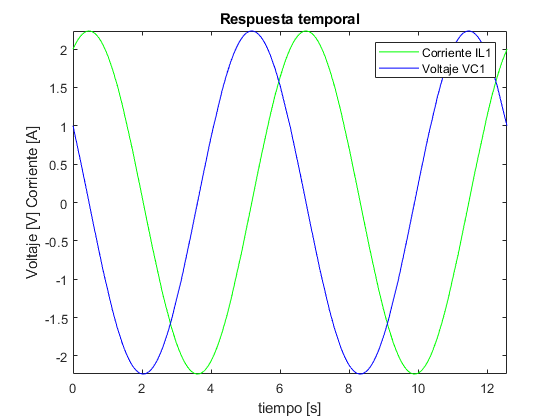

clf;
fplot(iSol,[ti,tf],'-g')
hold on
fplot(vSol,[ti,tf],'-b')
title('Respuesta temporal')
xlabel('tiempo [s]')
ylabel('Voltaje [V] Corriente [A]')
legend({'Corriente IL1','Voltaje VC1'})
hold off

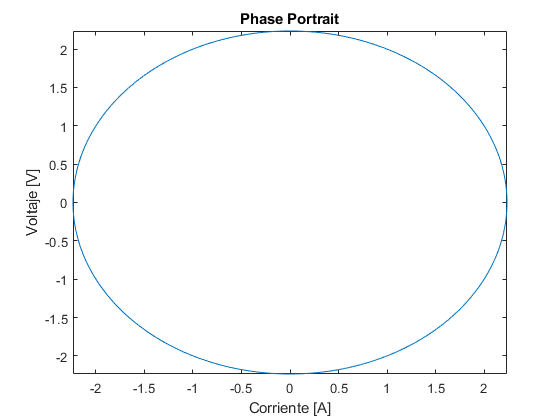

fplot(iSol,vSol)
title('Phase Portrait')
xlabel('Corriente [A]')
ylabel('Voltaje [V]')
hold off